# *ME 599F - Robotics, Vision, Mechtronics for Manufacturing*

## Lab 2:Aditya Mahendru, Keeranat Kolatat, Munzir Abdulmajid

### Q1

We have prepared 20 images of a chessboard taken from a fixed-focus camera mounted at the gripper of a UR5e robot and a video input.avi recorded from the same camera when the robot was following a trajectory. Complete the following tasks.

**A)** [Camera calibration] Run the provided code *camera_calibration.m*. The code will calibrate the camera using the given images and chessboard size. Read the code and observe the obtained calibration results. What is the estimated camera matrix $K$? See textbook equation (11.7) for $K$’s definition

clear all
close all
clc

camera_calibration
K 

K = 	1.0e+03 *

    1.3584         0    0.7671
         0    1.3584    0.5624
         0         0    0.0010


rho_w = 1/K(1,1);
rho_h = 1/K(1,1);
u_0 = K(1,3);
v_0 = K(2,3);

`------`

**B)** [Pose estimation] Run provided code *pose_estimation.m*. The code will estimate the pose of camera with respect to the chessboard for each frame contained in the imported video. Then the camera’s moving trajectory could be visualized. Read the code and observe the generated figure. List at least three factors that you think will affect the pose estimation accuracy.

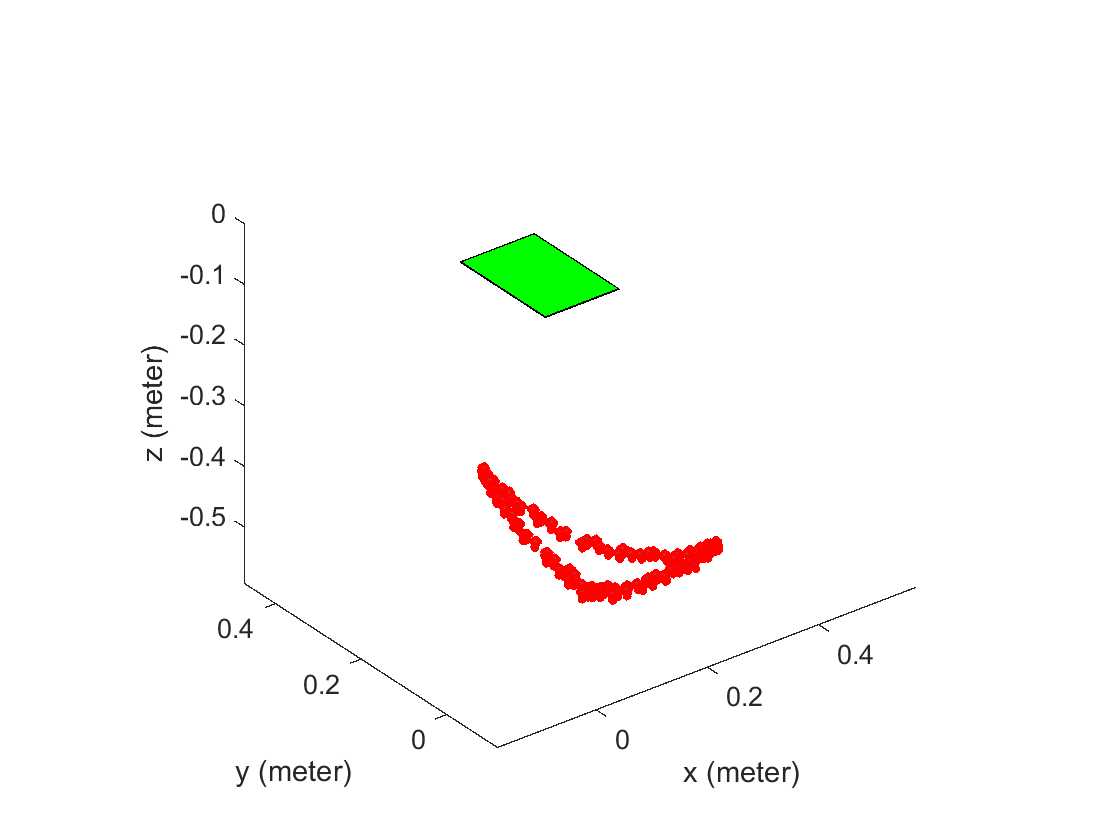

pose_estimation

The three factors that will affect the pose estimation accuracy are lens distortion, pixel error, and background scene.

`------`

**C)** [Camera projection] You have obtained the camera intrinsic parameters and camera pose for each frame. Imaging that three physical lines are attached to the chessboard. Each line represents one axis of the chessboard’s coordinate system. Assuming central projection model, we can visualize them in each image frame and generate an output video. We have provided the code *camera_projection.m* to do this job. You will need to complete the function *cameraProjection.m* which returns the image coordinates of projected points given their coordinates in 3D (defined in chessboard coordinates system), the relative pose between camera and chessboard and camera intrinsic parameters. MATLAB has a function called *worldToImage* that can do the same task but you need to implement your own. If implemented correctly, you should see a generated video *output.mp4* (one frame shown below). Submit the video. Ignore the lens distortion parameters since they are very small. 

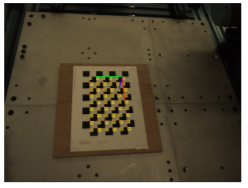

Figure 1: One frame in the generated video. 

camera_projection

Error using camera_projection (line 3)
Cannot create file output. Permission Denied.

`------`

### Q2 - Kinematic Motion Control

 In this problem, you will exploit resolve-rate kinematic control with and without degenerate configurations. Follow the problem statements closely

**A)** Load the puma560 robot into MATLAB workspace. Validate that the canonical joint configuration *qr* is degenerate. Visualize this joint configuration using *p560.teach()* or *p560.plot()*. 

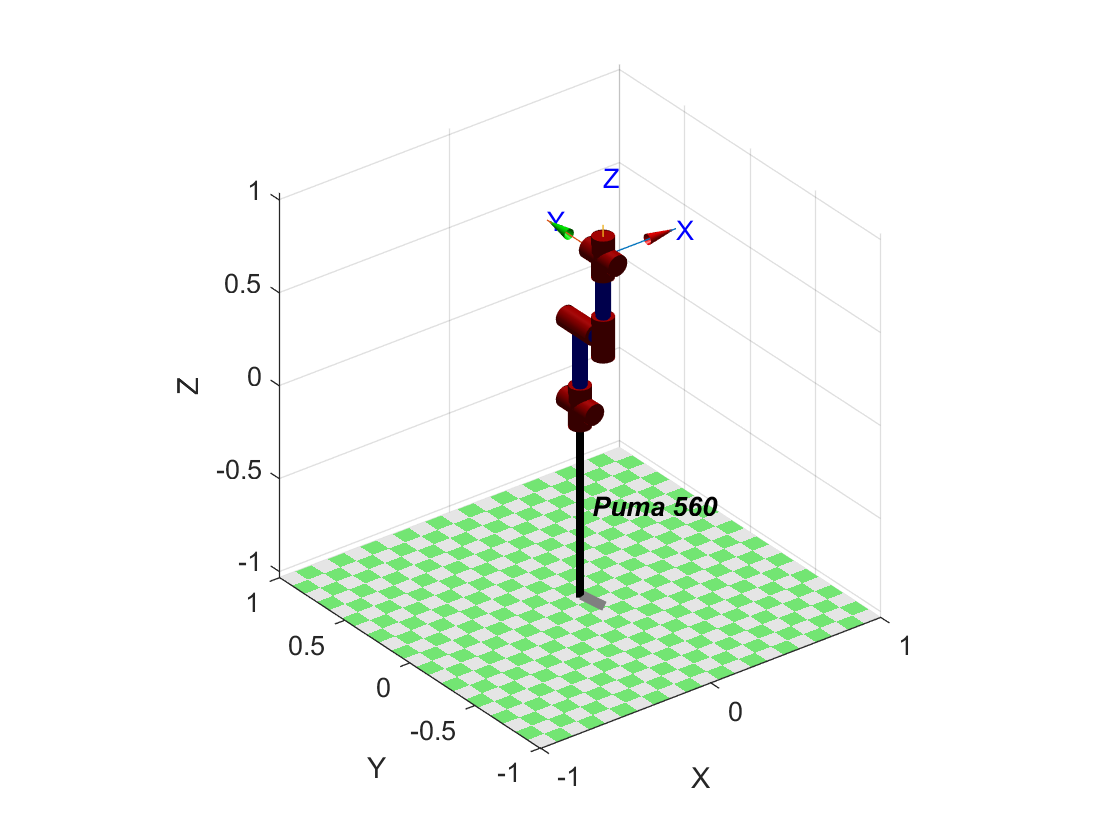

clear all; 
close all; 
clc;

mdl_puma560
p560.plot(qr); 

J = p560.jacob0(qr)

J =     0.1500   -0.8636   -0.4318         0         0         0
    0.0203    0.0000    0.0000         0         0         0
         0    0.0203    0.0203         0         0         0
         0         0         0         0         0         0
         0   -1.0000   -1.0000         0   -1.0000         0
    1.0000    0.0000    0.0000    1.0000    0.0000    1.0000


 det(J)

ans = 0

When det(J) = 0, the robot configuration is singular/degenerate. This occurs when the robot is at maximum reach or one or more axes become aligned resulting in the loss of DOF

`------`

**B)** Load the open-loop resolve-rate motion control simulink file *sl_rrmc*. Run the simulink to obtain the default result to move at a Cartesian velocity of [0, 0.05, 0, 0, 0, 0], starting from an initial joint angle of [0, π/4, π, 0, π/4, 0] . Validate this default initial joint angle is non-degenerate. Change the initial joint angles to qr’ (note the need for the transpose sign for compatible dimensions). Run the simulink again and explain why the open-loop resolve-rate motion control does not work in this case.

sl_rrmc
%det(J) = 0.0786 > non-degenarate
%The matrix has to be [6x1] and qr' isn't a [1x6] matrix.

`------`

**C)** Close *sl_rrmc*. Load the simulink model *sl_rrmc_dinv_cl* that is available from the course canvas. The default configuration gives you closed-loop kinematic motion control from a starting joint configuration of *qn* to the desired joint configuration qr. Write down the control logic from q[k] to q[k + 1]:


$$q\left\lbrack k+1\right\rbrack =q\left\lbrack k\right\rbrack +\Delta t\cdot q\left\lbrack k\right\rbrack =q\left\lbrack k\right\rbrack +\Delta t\cdot {J\left(q\left\lbrack k\right\rbrack \right)}^{-1} \upsilon$$


**C.i) **Limits of P control: a steady error exists in the achieved joint angles - move your cursor in the generated figure to see, and in the MATLAB command line, verify numerically the difference between q.out(:,:,end) and qr’. Obtain the norm of the error vector by *norm(rad2deg(wrapToPi(out.q(:,:,end)))- rad2deg(wrapToPi(qr’)))*. Check also *norm(rad2deg(out.q(:,:,end))-rad2deg(qr’))* and explain the difference.

sl_rrmc_dinv_cl

norm(rad2deg(wrapToPi(out.q(:,:,end)))- rad2deg(wrapToPi(qr)))

ans = 311.7691

norm(rad2deg(out.q(:,:,end))-rad2deg(qr))

ans = 933.2719

The difference is that the error multiplied by 3.

`------`

**C.ii) **From P to PI control: gradually increase the gain Ki from 0 to 5, simulate and verify that the norm of the steady-state joint error *norm(rad2deg(wrapToPi(out.q(:,:,end)))-rad2deg(wrapToPi(qr’)))* decreases. Plot how the norm evolves with respect to Ki.

norm(rad2deg(wrapToPi(out.q(:,:,end)))-rad2deg(wrapToPi(qr)))

ans = 311.7691

Ki = [0.5,1,2,3,4,5]

Ki =     0.5000    1.0000    2.0000    3.0000    4.0000    5.0000


Error = [317.3017,315.5492,312.4194,311.8317,311.7702,311.7691]

Error =   317.3017  315.5492  312.4194  311.8317  311.7702  311.7691


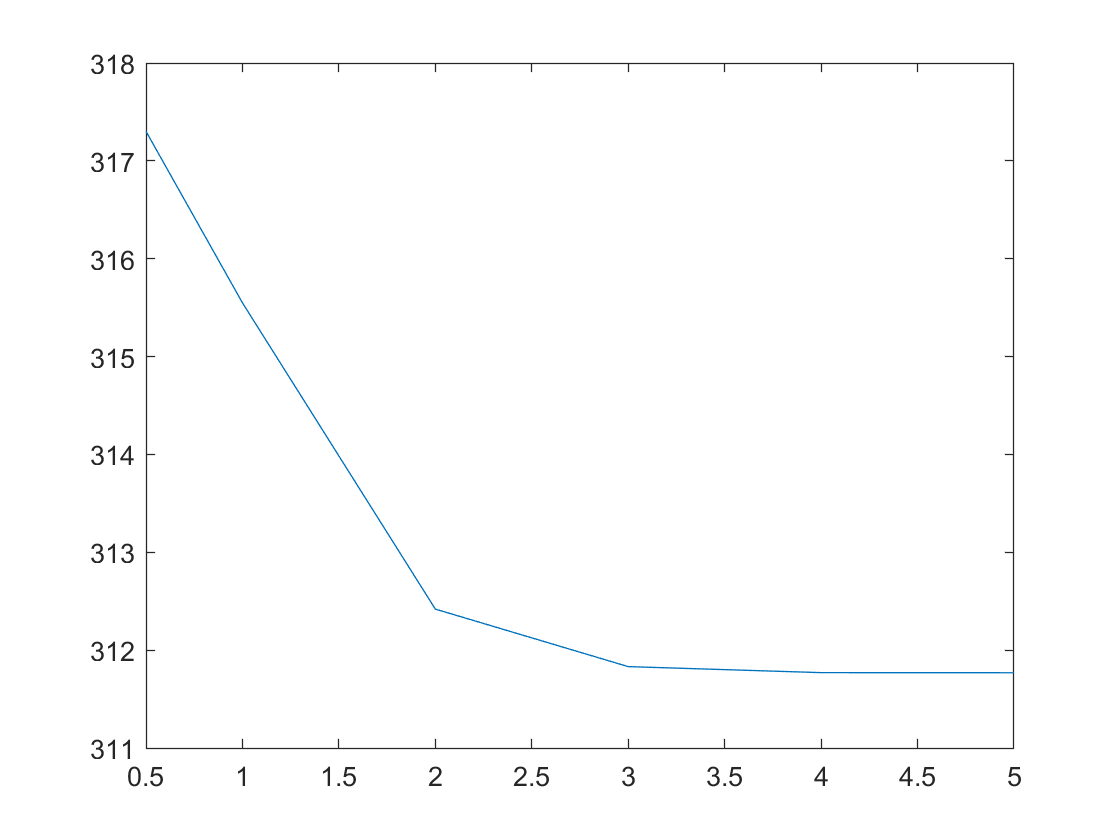

figure
plot(Ki, Error)

`------`

**C.iii) **Set the Ki gain back to 0. Change the initial joint angles to *qr*’ and the desired joint angles to *qn*’+0.5. Run the simulation and explain why the simulation experiences errors. In the cyan gain block named “K damped inverse”, try changing the gain to a small number and rerun the simulation. Explain why the simulation can run successfully this time, and plot the error norm, *norm(rad2deg(wrapToPi(out.q(:,:,end)))-rad2deg(wrapToPi(qn’+0.5)))*, with respect to your tested values of “K damped inverse”.

The simulation experiences errors because the Jacobian system is singular

The simulation can run successfully this time after changing the K damped inverse because the Jacobian matrix is nonsingular due to the K damped inverse 6x6 matrix.

norm(rad2deg(wrapToPi(out.q(:,:,end)))-rad2deg(wrapToPi(qn+0.5)))

ans = 458.9118


K = [0.1,0.2,0.3,0.4,0.5]

K =     0.1000    0.2000    0.3000    0.4000    0.5000


Error2 = [832.8764,737.1665,821.7921,458.9118,458.9118]

Error2 =   832.8764  737.1665  821.7921  458.9118  458.9118


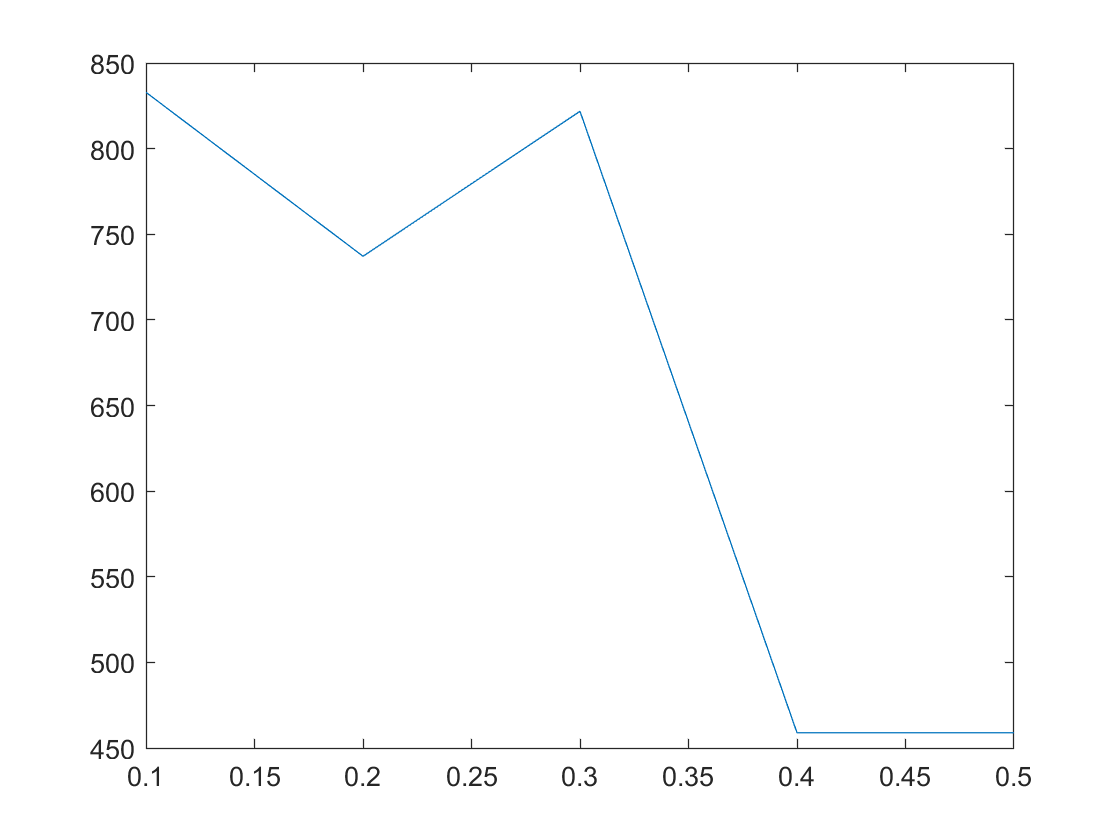

figure
plot(K, Error2)

`------`

**C.iv) **Extra 10% credit: one intuition to improve the control design is to initiate “K damped inverse” with a non-zero value to address the singularity at the initial pose, and to reduce the gain to zero when the robot is away from the singularity. Design the simulink and test this intuition. Submit the simulink file and a screen recording of the best robot motion you achieved. Provide the final error norm *norm(rad2deg(wrapToPi(out.q(:,:,end)))-rad2deg(wrapToPi(qn’+0.5)))*.

`------`